================================================================================

# Práctica 11. Integración numérica

#### Ejercicio 1. Fórmulas de Newton-Cotes

Consideramos la integral


$$\int_0^1 \sqrt{1-x^2}dx.$$


- Calcular el valor que da MATLAB.

- Representar la función en ese intervalo y representar gráficamente los puntos y polinomios que se utilizan para los métodos (simples) (a) del punto medio, (b) de los trapecios, (c) de Simpson y (d) de Boole.

clear all
format long

f = @(x) sqrt(1-x.^2);
min = 0;
max = 1;

integral_result = integral(f, min, max)

integral_result =    0.785398163397448


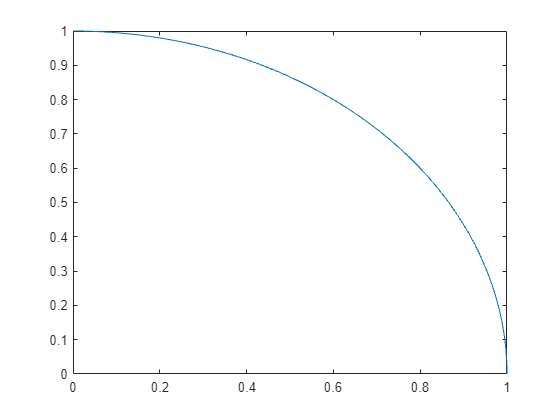

% Faltan cositas...
fplot(f, [0 1])

#### Ejercicio 2. Integración de Romberg

Implementar de manera eficiente la integración de Romberg para conseguir un error de orden $\mathcal{O}(h^{32})$ con $h=1/2$ y calcular el error absoluto en la integración de la siguiente función:


$$\int_0^1 \sqrt{1-x^2}dx.$$


clear all
format long

f = @(x) sqrt(1-x.^2);
min = 0;
max = 1;
h = 1/2;

integral_matlab = integral(f, min, max)

integral_matlab =    0.785398163397448


% Intento de hacer anonima la formula del trapecio :(
% trapecio = @(f, h) (abs(h(2) - h(1)) / 2) * ( f(h(1)) + 2*sum( linspace(min,max,abs(h(2) - h(1))) ) + f(h(2)) );

val_primal_funcion = calcula_trapecio(f, [0 1], 1/2)

val_primal_funcion =    0.683012701892219


% Para comprobar
val_primal = (0.5 / 2) * ( f(0) + 2*sum( f(0.5) ) + f(1) )

val_primal =    0.683012701892219


R = zeros(16);

for k = [1:16] 
    for j = [k:16]
        h = (max-min) / 2^j;

        if k == 1
            R(j,k) = calcula_trapecio(f, [0 1], h);
        else
            R(j,k) = (4^(k-1)*R(j, k-1) - R(j-1, k-1)) / (4^(k-1) - 1);
        end
    end
end

R

R =    0.683012701892219                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
   0.748927267025610   0.770898788736741                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
   0.772454786089293   0.780297292443854   0.780923859357662                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
   0.780813259456935   0.78359941

aprox_romberg = R(16,16)

aprox_romberg =    0.785398157618301


error_absoluto = abs(aprox_romberg - integral_matlab)

error_absoluto =      5.779147715934130e-09


#### Ejercicio 3. Integración adaptativa

Calcular de manera adaptativa la siguiente integral con tolerancia $10^{-7}$. Representar la función y todos los puntos que se han usado para obtenerla.


$$\int_0^4e^{-2x} \sin(3x) + 0.5 dx$$


clear all
format long

f = @(x) exp(-2.*x).*sin(3.*x) + 0.5;
min = 0;
max = 4;

fplot(f, [min max])
hold on

val_matlab = integral(f, min, max)

val_matlab =    2.230731596609429


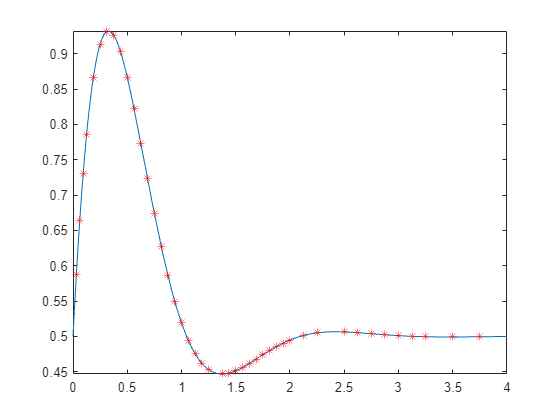

tolerancia = 10^-7;

calcula_simpson(f, [min max], tolerancia, val_matlab);

hold off

#### Ejercicio 4. Integración de Montecarlo

- Estimar $\pi$ usando el método hit-or-miss con 1000 puntos aleatorios y un círculo de radio unidad. Representar el método y calcular el error absoluto.

- Usar la integración de Montecarlo por media muestral para aproximar la siguiente integral usando 1000 números aleatorios.

                
$$\int_1^2 (4-x^2)^{3/2}dx.$$


            Dar el error absoluto.

#### Ejercicio 5. Integración gaussiana

Integrar la siguiente función usando ocho puntos y el método de Gauss-Legendre:


$$\int_0^4e^{-2x} \sin(3x) + 0.5 dx.$$


Calcular el error absoluto.

*Nota: puede ayudar para los pesos calcular los ceros del polonomio de Legendre *$P_n(x)$ *que da MATLAB en simbólico (las funciones vpasolve() y legendreP() pueden ayudar para esto). Los pesos vienen dados por la fórmula*

${\displaystyle w_{i}={\frac {2}{\left(1-x_{i}^{2}\right)\left[P'_{n}(x_{i})\right]^{2}}}}$* donde los *$x_i$* son los nodos. (Cuidado, el polinomio está derivado en esta fórmula.)*

#### Funciones internas

function trapecio = calcula_trapecio(f, intervalo, h)
    % trapecio = @(f, h) (abs(h(2) - h(1)) / 2) * ( f(h(1)) + 2*sum( puntos medios ) + f(h(2)) );
    
    b = intervalo(1) + h;
    sumas = 0;

    while b < intervalo(2)
        sumas = sumas + f(b);
        b = b + h;
    end

    trapecio = h/2 * (f(intervalo(1)) + 2*sumas + f(intervalo(2)));
end

function calcula_simpson(f, intervalo, tolerancia, val_real)
    
    h = (intervalo(2) - intervalo(1)) / 2;
    mid = (intervalo(2) + intervalo(1)) / 2;

    intervalo1 = [intervalo(1) mid];
    h_I1 = (intervalo1(2) - intervalo1(1)) / 2;
    mid_I1 = (intervalo1(2) + intervalo1(1)) / 2;

    intervalo2 = [mid intervalo(2)];
    h_I2 = (intervalo2(2) - intervalo2(1)) / 2;
    mid_I2 = (intervalo2(2) + intervalo2(1)) / 2;

    simpson_I0 = h/3 * (f(intervalo(1)) + 4*f(mid) + f(intervalo(2)) );
    simpson_I1 = h_I1/3 * (f(intervalo1(1)) + 4*f(mid_I1) + f(intervalo1(2)) );
    simpson_I2 = h_I2/3 * (f(intervalo2(1)) + 4*f(mid_I2) + f(intervalo2(2)) );

    error = 1/10 * abs(simpson_I1 + simpson_I2 - simpson_I0);

    if error > tolerancia
        plot(mid, f(mid), "*", "color", "r")
        calcula_simpson(f, intervalo1, tolerancia/2, val_real);
        calcula_simpson(f, intervalo2, tolerancia/2, val_real);
    end
    
end

`Documento preparado por I. Parada, 15 de mayo de 2024`